# 狄卡文章爬蟲 Dcard Forums Postes Crawler

## 版本號 Version Dev.0 (測試版本 R2021a)

 ============================ 

#### 工具箱需求 Toolbox Requirement: 

- [文本分析工具箱 Text Analytics Toolbox] 

- [結巴中文斷詞 jieba] [https://github.com/fxsjy/jieba](https://github.com/fxsjy/jieba) 

============================ 

#### 參數說明 : 

- forumsList: 抓取Dcard看板列表 

- forum: 目標抓取看板 

- isPopular: 是否抓取看板熱門文章 

- limit: 單次抓取文章數量限制 

- iter: 抓取次數 

============================ 

***Python 版本: 3.7-3.8*** 

============================ 

狄卡 Dcard API: [https://www.dcard.tw/service/api/v2/](https://www.dcard.tw/service/api/v2/) 

============================ 

***MATLA支援版本: R2020b-R2022b*** 

在MATLAB中使用自訂義Python模組 Call User-Defined Python Module: [https://www.mathworks.com/help/matlab/matlab_external/call-user-defined-custom-module.html](https://www.mathworks.com/help/matlab/matlab_external/call-user-defined-custom-module.html)

## Initialization

clear,clc
close all
% web(https://www.dcard.tw/f/food?latest=true)

## API 與參數設定 Website API and Variables Configuration

api = 'https://www.dcard.tw/service/api/v2/';
forumListAPI = 'https://www.dcard.tw/service/api/v2/forums';
isPopular = false;
limit = 30;
iter = 10;
queryDelimiter = '&';

## 看板列表資訊爬取 Forum List Crawling

forumsData = webread(forumListAPI);
pause(5)

## 看板原始資料整理 Extract Forum List Information From Raw Data

forumsList = cellfun(@ExtractForumInfo,forumsData,'UniformOutput',false);
forumsList = vertcat(forumsList{:});

## 看板文章爬取 Forum Posts Crawling

forum = 'food';
forumQuery = ['/forums/',forum];
switch isPopular
    case true
        popStr = 'true';
    case false
        popStr = 'false';
end
isPopularQuery = ['&popular=',popStr];
limitQuery = ['&limit=',num2str(limit)];

url = [api,forumQuery,'/posts?',isPopularQuery,limitQuery];
Data = webread(url,opt);

Error using matlab.internal.webservices.HTTPConnector/copyContentToByteArray
The server returned the status 429 with message "Too Many Requests"
in response to the request to URL
https://www.dcard.tw/service/api/v2//forums/food/posts?&popular=false&limit=30.

Error in readContentFromWebService (line 46)
        byteArray = copyContentToByteArray(connection);

Error in 

dcardTable = cellfun(@ExtractArticleInfo,Data,'UniformOutput',false);
dcardTable = vertcat(dcardTable{:});

% For-loop 爬取多篇文章
% 系統訊息
SelectedForum = forumsList.Name(find(forumsList.Alias == forum));
fprintf('***** 開始爬取看板: %s *****\n',SelectedForum)
try
    for i = 1:iter
        fprintf('爬取文章區塊: %.0f/%.0f \n',i,iter) % 進度訊息
        latestID = min(dcardTable.id);
        beforeQuery = ['&before=',num2str(latestID-1)]; % 抓取早於latestID的limit數文章文章
        url = [api,forumQuery,'/posts?',isPopularQuery,limitQuery,beforeQuery];
        Data = webread(url);
        if ~isempty(Data)
            dcardTable_part = cellfun(@ExtractArticleInfo,Data,'UniformOutput',false);
            dcardTable = [dcardTable;vertcat(dcardTable_part{:})];
        else
            disp('無更多資料擷取')
            break
        end
    end
    fprintf('爬取成功! 共爬取到%.0f篇文章\n',height(dcardTable))
catch errMsg
    error('爬取失敗')
end

## 顯示爬取結果

head(dcardTable)

ans = 8×10 table
        id                           title                                                                                                      excerpt                                                                                        createdTime              updatedTime         gender        school          department      commentCount    likeCount
    __________    ___________________________________________    _____________________________________________________________________________________________________________________________________________________________________    _____________________    _____________________    ______    _______________    _____________

## 使用結巴針對文章標題進行斷詞與字符清理 Word Segementation with jieba and Erase Punctuation

此區塊程式碼使用MATLAB文本分析工具箱涵式 Required MATLAB Text Analytics Toolbox 此區塊程式碼使用Python Required Python

titleWord = dcardTable.title;
str = erasePunctuation(titleWord);
splitData = arrayfun(@py.JiebaSeg.WordSeg,str,'UniformOutput',false);

Building prefix dict from the default dictionary ...
Dumping model to file cache C:\Users\Tim\AppData\Local\Temp\jieba.cache
Loading model cost 0.925 seconds.
Prefix dict has been built successfully.


strValue = cellfun(@(x)string(erasePunctuation(strsplit(char(x)))),splitData,'UniformOutput',false);
strValue = cat(2,strValue{:});

## 建立字辭典 Create Tokenized Documentation

此區塊程式碼使用MATLAB文本分析工具箱涵式 Required MATLAB Text Analytics Toolbox

document = tokenizedDocument(strValue);
% tbl = textrankKeywords(document);
% if size(tbl.Keyword,2) > 1
%     tbl.Keyword = strip(join(tbl.Keyword));
% end

## 透過文字雲視覺化標題結果 Visualization with Wordcloud

此區塊程式碼使用MATLAB文本分析工具箱涵式 Required MATLAB Text Analytics Toolbox

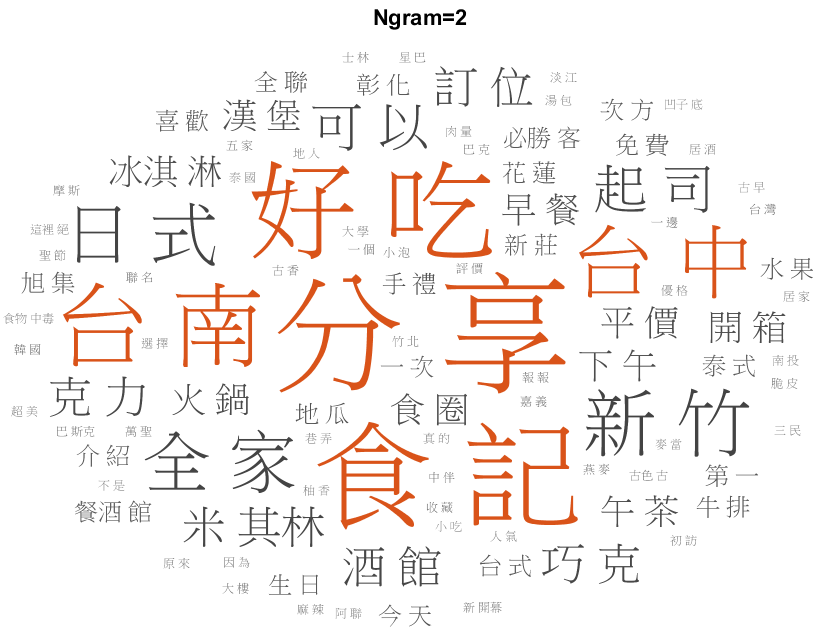

figure
bag = bagOfNgrams(document,'NgramLengths',2);
wordcloud(bag);
title('Ngram=2')

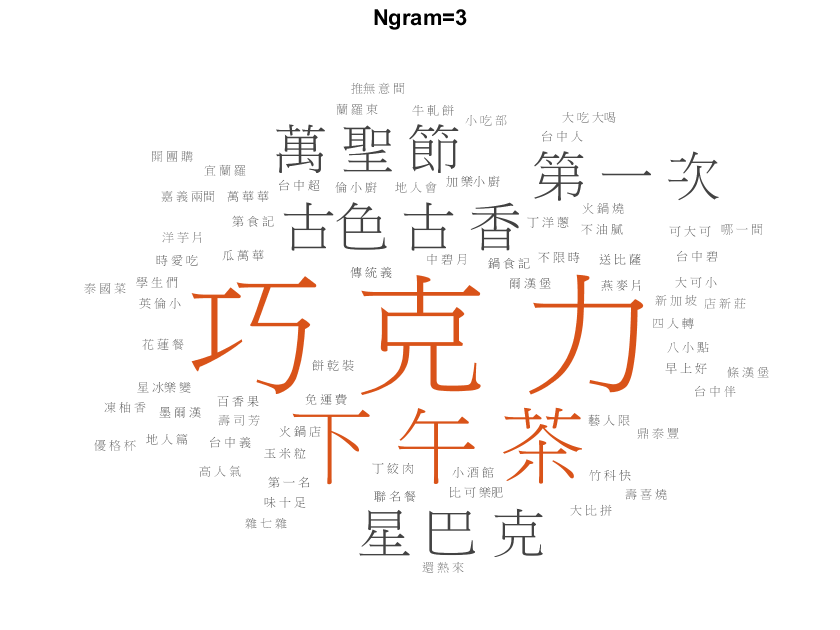


figure
bag = bagOfNgrams(document,'NgramLengths',3);
wordcloud(bag);
title('Ngram=3')

## Helper Function

% 建立看板列表中英代號對照表

function infoTable = ExtractForumInfo(this)
Name = string(this.name);
Alias = string(this.alias);
infoTable = array2table([Name,Alias],'VariableNames',{'Name','Alias'});
end

% 擷取文章資訊
function extractData = ExtractArticleInfo(this)
% 確認是否隱藏學校與系所
anonymousSchool = this.anonymousSchool;
anonymousDepartment = this.anonymousDepartment;
% 預設變數
id = "";
title = "";
excerpt = "";
createdTime = "";
updatedTime = "";
gender = "";
commentCount = "";
likeCount = "";
topics = "";
media = "";
school = "";
department = "";
% 變數資訊擷取
id = this.id;
title = convertCharsToStrings(this.title);
excerpt = convertCharsToStrings(this.excerpt);
createdTime = this.createdAt;
updatedTime = this.updatedAt;
commentCount = this.commentCount;
likeCount = this.likeCount;
gender = convertCharsToStrings(this.gender);

% 條件變數資訊擷取
if ~isempty(this.topics)
    topics = this.topics;
end

if ~anonymousSchool
    school = convertCharsToStrings(this.school);
end

if ~anonymousDepartment
    department = convertCharsToStrings(this.department);
end

if this.withImages || this.withVideos
    media = this.media;
end

createdTime = datetime(createdTime,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSZ','TimeZone','Asia/Taipei','Format','uuuu年M月d日 HH:mm:ss');
updatedTime = datetime(updatedTime,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSZ','TimeZone','Asia/Taipei','Format','uuuu年M月d日 HH:mm:ss');
extractData = table(id,title,excerpt,createdTime,updatedTime,gender,school,department,commentCount,likeCount);
end